# IMU Data Analysis Documentation

## 1. Introduction to IMU - Inertial Measurement Unit

Inertial Measurement Units (IMUs) are electronic devices used to measure and report a body's specific force (acceleration) and angular rate (angular velocity). Our system, named INDIP, utilizes a Magneto Inertial Measurement Unit (MIMU) comprising accelerometers, magnetometers, and additional sensors like distance and pressure sensors. These sensors collectively provide rich data about the motion and orientation of the system.

## 2. Raw Data

The raw data collected from our IMU system includes triaxial vertical acceleration, angular velocity, and magnetic field readings. These data streams are typically stored in CSV (Comma-Separated Values) or MAT (MATLAB Data File) formats. Below is an example snippet of raw data:

% load the raw IMU data 
data = readtable('E:\New\DOCUMENTS\Projects\kone\projects\2023 L400 FYP\database\FYP\FYP\RF\P 1\Trial 2\right_foot.txt');

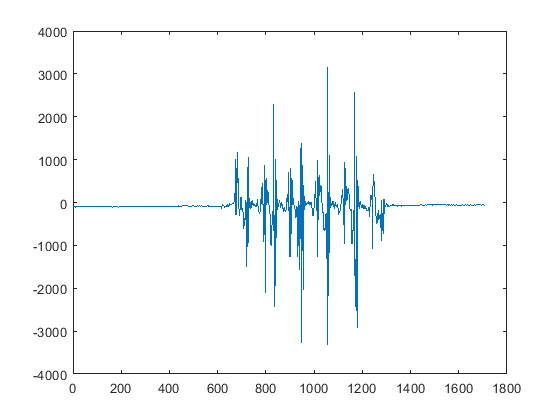

% visualize the raw data  
plot(data.Acc_X);

## 3. Step Detection Algorithm

A crucial aspect of IMU data analysis is the detection of steps or movements. We've implemented a step detection algorithm based on signal processing techniques such as peak detection and thresholding. Here's a simplified version of the algorithm pseudocode:

pythonCopy code

Explain`# Step Detection Algorithm``def` `detect_steps``(``acceleration_data``): steps = [] ``for`` i ``in` `range``(``1``, ``len``(acceleration_data) - ``1``): ``if`` acceleration_data[i] > threshold ``and`` acceleration_data[i] > acceleration_data[i - ``1``] ``and`` acceleration_data[i] > acceleration_data[i + ``1``]: steps.append(i) ``return`` steps `

## 4. Sensor Fusion

Sensor fusion techniques are employed to combine data from multiple sensors to improve accuracy and robustness. Our system utilizes quaternion estimation and Euler angles calculation for sensor fusion purposes. The following diagram illustrates the sensor fusion process:

## 5. Integration with OpenSim

OpenSim is an open-source software platform for modeling and simulation of movement. Our integration, known as OpenSense, enables seamless transfer of IMU data into OpenSim for further analysis and modeling. Below is an example workflow demonstrating how IMU data is integrated with OpenSim:

[insert workflow here]

Explain

`# Integration with OpenSim``import`` opensim ``# Load IMU data``imu_data = load_imu_data(``'imu_data.csv'``) ``# Create OpenSim model``model = opensim.Model() ``# Add markers based on IMU data``for`` data_point ``in`` imu_data: marker = opensim.Marker(data_point.position) model.add_marker(marker) `

## 6. Inverse Kinematics

Inverse kinematics is a computational technique used to determine the joint parameters necessary to position a model in a desired configuration. Our system implements the Rajapogal protocol for model scaling and inverse kinematics calculations. Here's an example of how inverse kinematics is performed using MATLAB:

matlabCopy code

Explain

`% Inverse Kinematics in MATLAB % Load OpenSim model and IMU data model = load_model('model.osim'); imu_data = load_imu_data('imu_data.csv'); % Perform inverse kinematics solution = inverse_kinematics(model, imu_data); % Display results disp(solution); `

## 7. Recent Developments

In recent developments, we have further enhanced our IMU data analysis capabilities by leveraging MATLAB for inverse kinematics computations. This integration streamlines the analysis process and improves efficiency. Below is a snippet demonstrating the use of MATLAB for inverse kinematics:

matlabCopy code

Explain`% MATLAB for Inverse Kinematics % Load model and IMU data model = load_model('model.osim'); imu_data = load_imu_data('imu_data.csv'); % Perform inverse kinematics using MATLAB functions solution = perform_inverse_kinematics(model, imu_data); % Display results disp(solution); `

This expanded documentation provides more detailed explanations, code examples, and diagrams to facilitate understanding and implementation of IMU data analysis techniques.